# Second-Order Time Response

Demonstration of how to visualize the response of a canonical (underdamped) second order model.

## Canoncial model

The real part of the pole pair: $\zeta \, \omega_n$

zwn = 0.5;

The imaginary part of the pole pair: $\omega_d$

wd = 2*pi;    % rad/s

## Create the transfer function

num = zwn^2 + wd^2;
den = conv([1 zwn],[1 zwn]) + [0 0 wd^2];
G = tf( zwn^2 + wd^2, den)


G =
 
       39.73
  ---------------
  s^2 + s + 39.73
 
Continuous-time transfer function.
Model Properties


## Plot the unit step response

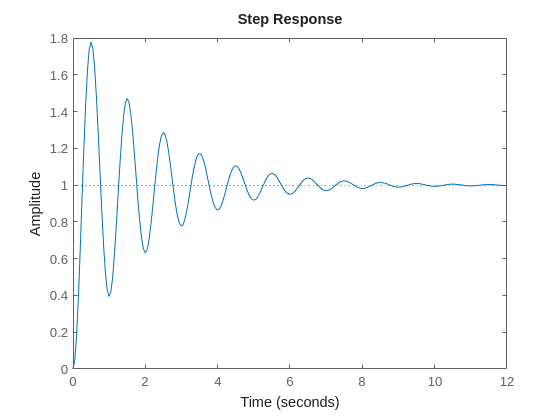

figure(1)
clf()
step(G)

Note that the "DC Gain", $K_{dc}$ is unity.

## Plot the unit impulse response

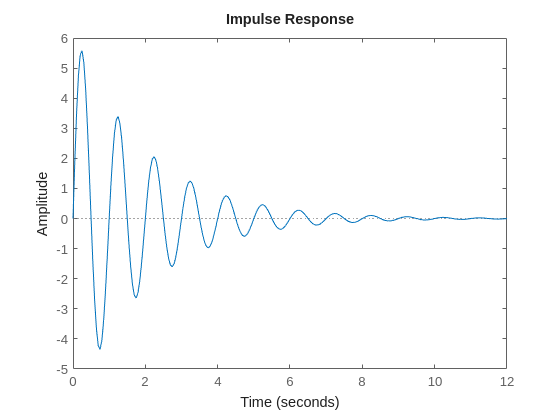

figure(2)
clf()
impulse(G)

Overlay the analytical solution for the impulse response to verify that they are consistent.

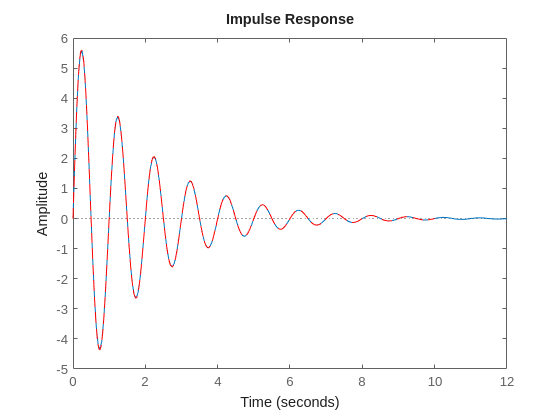

hold on
tt = linspace(0,10,1000);
cc = (zwn^2+wd^2)/wd*exp(-zwn*tt).*sin(wd*tt);
plot(tt,cc,'r--')